# Concentration Mapping

This Workflow calculates the concentration for each vertex at the mesh. A prerequisite is the Workflow_ModellingGB. The modelled grainboundary in this workflow called GB is a patch array with faces and vertices. In addition, a decomposed pos file is required. 

## Calculation of the distance to the mesh

First of all, the distance of each atom is calculated. During the calculation each atom is adressed to the nearest vertex. loc the output variable is a table with the distance of each atom and the corresponding atom. 

loc = posDistanceToMesh(pos,GB6);
 

## Exclude all atoms with a distance wider than clipDist to the mesh 

clipDist = '2'; % is the maximum distance of an atom besides the mesh
posGB = pos(abs(loc.distance) < clipDist,:); %creates a pos file of the atoms at the mesh within the clipping distance
loc = loc(abs(loc.distance) < clipDist,:); % creates a loc table with the distances and the corresponding vertex number of the atoms withi the clipping distance to the mesh
 

## Voxelisation of the vertex 

posNdBin creates for each vertex an own pos file 

vox = posNdBin(posGB,loc.closestVertex,{((1:length(GB6.vertices)+1) - .5)'});
 

## Calculates the concentration for each vertex

numVerts = length(vox);
ck = @(posGB) posCalculateConcentrationSimple(posGB, .37, {}, 'map');
conc = binApplyConcentrationKernel(vox,{1:numVerts},ck,'idx');
 

## Displays the concentration of each vertex at the mesh 

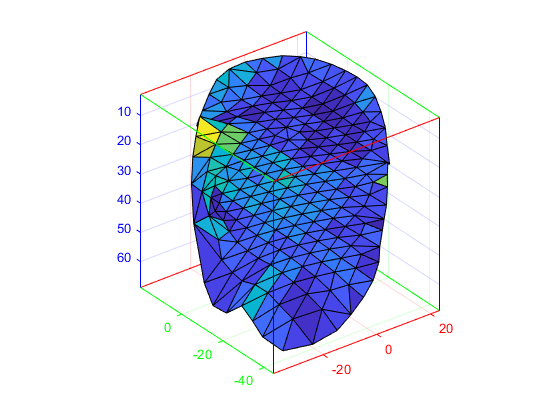

figure
Cmap = conc(conc.format == 'concentration',:).C;
trisurf(GB4.faces,GB4.vertices(:,2),GB4.vertices(:,1),GB4.vertices(:,3),Cmap);
axisSpatialAptify

ToDo 

- evtl bei conc dass jedes volumen nach seinem vertex heißt 

- function handle auch auf interface excess wert anwenden 

Fragen: 

- ck -> ist es wichtig ob pos oder posGB drinsteht? oder ist das nur generell dass man einfach ein pos file brauch, es kommt das gleiche raus

- wo sitzt genau der vertex? weil im Bild ist ja die ganze Fläche gelb? oder blau zum beispiel 